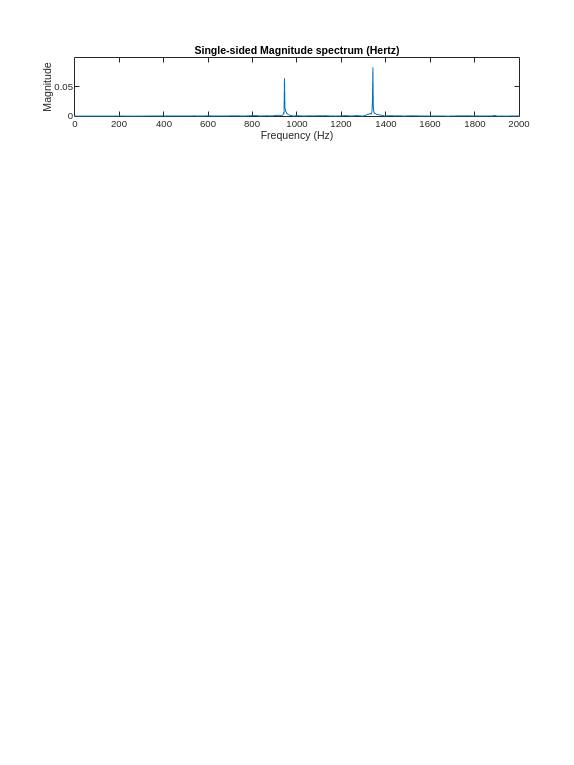

  944.1534

   1.3419e+03

Phone Number: 0


clear; clc; close all;
phone_number = 'phone_number_audio_recordings/phone_number_8.mp3';
function decode = decodeNum(phone_number)
    [phn,fs] = audioread(phone_number);
    phone_part1 = split(phone_number,'.');
    phone_call = split(phone_part1{1},'_');
    phn1 = phn(:,1);
    
    window_size = round(0.05 * fs);  
    smoothed_mag = movmean(abs(phn1), window_size);
    
    threshold = 0.05; 
    above_threshold = smoothed_mag > threshold;
    starts = find(diff([0; above_threshold]) == 1);
    ends = find(diff([above_threshold; 0]) == -1);
    figure('Position', [100, 100, 1200, 1600]);
    numSegments = length(starts);
    % Set up a tiled layout with compact spacing
    tiledlayout(7, 1, 'TileSpacing', 'compact', 'Padding', 'compact');
    decodedNumbers = [];
    numFreqMap = FreqMap();
    low_freqencies = [];
    high_frequencies = [];
    for i = 1:numSegments
        signal = phn1(starts(i):ends(i));
        nsamp = length(signal);
        x_mag = abs(fft(signal))/nsamp;
        bins = [0:nsamp-1];
        freq_hz = bins*fs/nsamp;
        % Plot only positive frequencies
        n_2 = ceil(nsamp/2);
        subplot(7, 1, i);
        plot(freq_hz(1:n_2), x_mag(1:n_2))
        max_mag = max(x_mag(1:n_2));
        axis([0,2000,0,1.2*max_mag]);
        xlabel('Frequency (Hz)')
        ylabel('Magnitude');
        title('Single-sided Magnitude spectrum (Hertz)');
        [pksF, locsF] = findpeaks(x_mag(1:n_2), 'SortStr', 'descend');
        freq1 = freq_hz(locsF(1));
        freq2 = freq_hz(locsF(2));
        lowFreq = min(freq1,freq2);
        highFreq = max(freq1,freq2);
        low_freqencies = [low_freqencies, lowFreq];
        high_frequencies = [high_frequencies, highFreq];
        number = mapFreqToNumber(lowFreq, highFreq, numFreqMap);
        decodedNumbers = [decodedNumbers, number];
        end
        
        disp(low_freqencies);
        disp(high_frequencies);
        disp(['Phone Number: ', num2str(decodedNumbers)]);
end

function numFreqMap = FreqMap()
    numFreqMap = containers.Map;
    numFreqMap('1') = [697, 1209];
    numFreqMap('2') = [697, 1336];
    numFreqMap('3') = [697, 1477];
    numFreqMap('4') = [770, 1209];
    numFreqMap('5') = [770, 1336];
    numFreqMap('6') = [770, 1477];
    numFreqMap('7') = [852, 1209];
    numFreqMap('8') = [852, 1336];
    numFreqMap('9') = [852, 1477];
    numFreqMap('0') = [941, 1336];
    numFreqMap('*') = [941, 1209];
    numFreqMap('#') = [941,1477];
end

function number = mapFreqToNumber(f1, f2, numFreqMap)
    keys = numFreqMap.keys;
    for k = 1:length(keys)
        freqPair = numFreqMap(keys{k});
        if (abs(f1 - freqPair(1)) < 20 && abs(f2 - freqPair(2)) < 20) || ...
           (abs(f1 - freqPair(2)) < 20 && abs(f2 - freqPair(1)) < 20)
            number = keys{k};
            return;
        end
    end
end

decodeNum('phone_number_audio_recordings/phone_number_0.mp3')

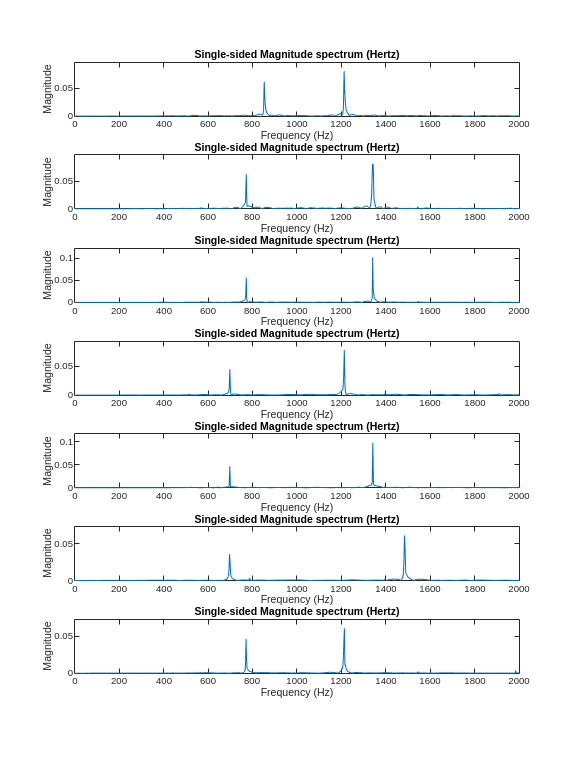

  852.9594  772.0731  772.1395  698.2267  698.0474  696.7630  771.0175

   1.0e+03 *

    1.2124    1.3401    1.3411    1.2134    1.3417    1.4842    1.2138

Phone Number: 7551234


decodeNum('phone_number_audio_recordings/phone_number_1.mp3')

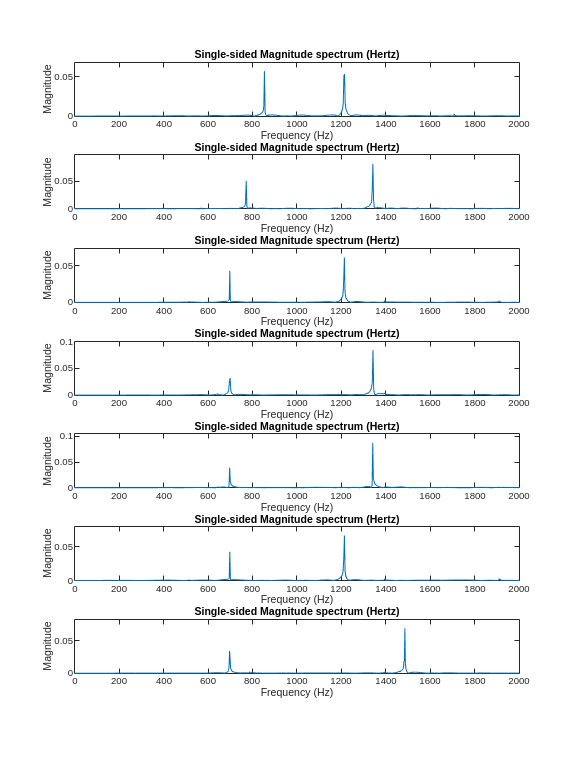

  854.0243  771.9133  698.0201  699.5241  697.4899  698.0865  697.0882

   1.0e+03 *

    1.2144    1.3419    1.2137    1.3424    1.3413    1.2139    1.4859

Phone Number: 7512213


decodeNum('phone_number_audio_recordings/phone_number_2.mp3')

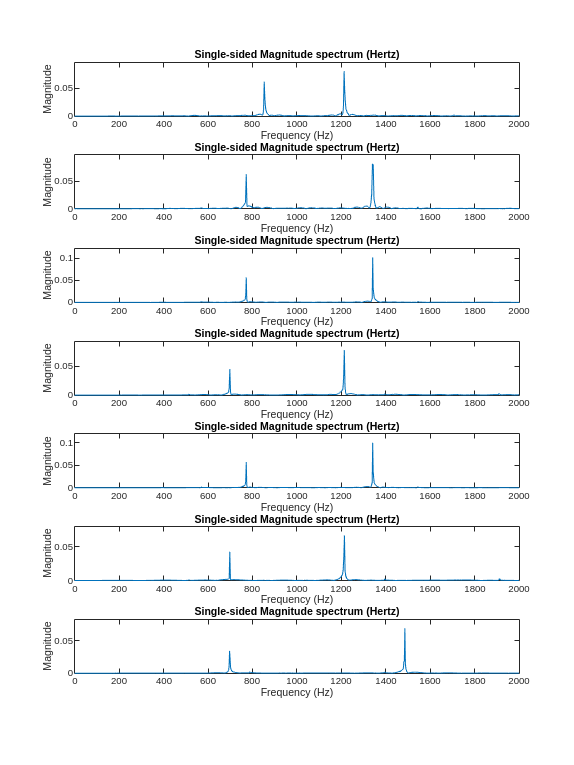

  852.9594  772.0731  772.1395  698.2267  772.0999  698.0865  697.0882

   1.0e+03 *

    1.2124    1.3401    1.3411    1.2134    1.3410    1.2139    1.4859

Phone Number: 7551513


decodeNum('phone_number_audio_recordings/phone_number_3.mp3')

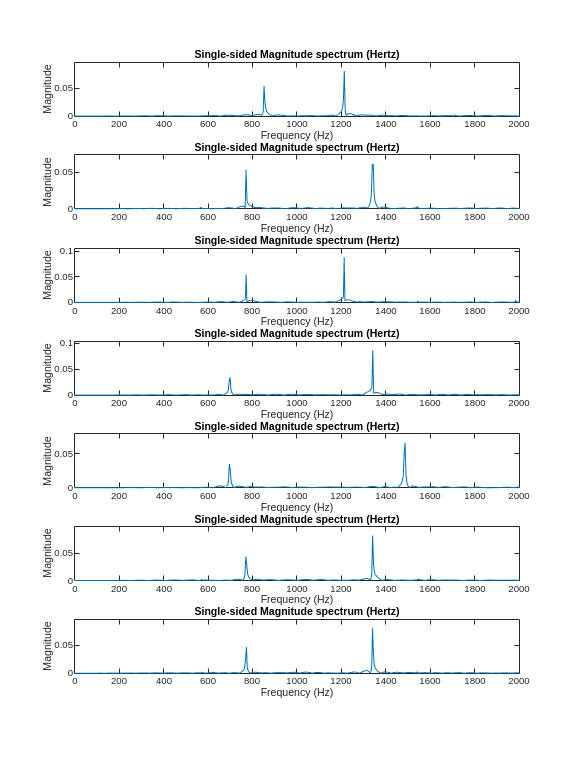

  852.2131  771.2110  771.7500  699.5428  696.0123  770.2523  772.9636

   1.0e+03 *

    1.2134    1.3434    1.2127    1.3415    1.4867    1.3408    1.3406

Phone Number: 7542355


decodeNum('phone_number_audio_recordings/phone_number_4.mp3')

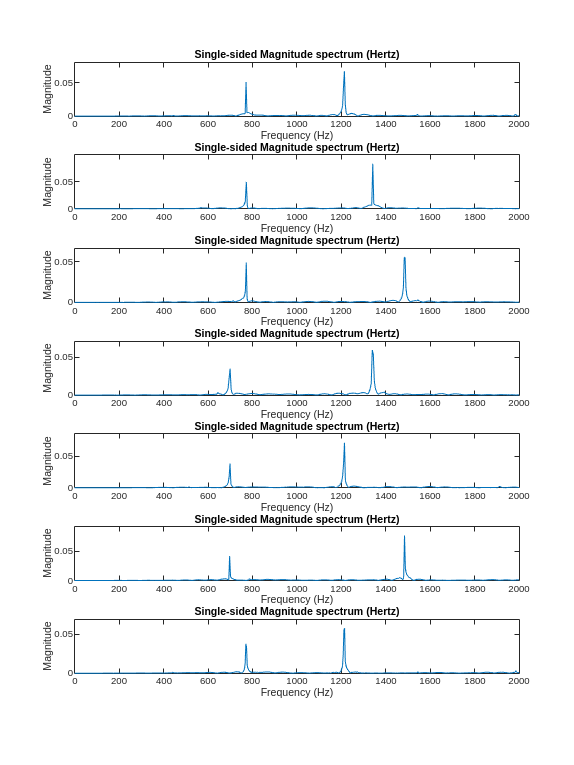

  771.2629  772.4670  772.1418  699.4887  699.0267  697.3410  770.4142

   1.0e+03 *

    1.2137    1.3414    1.4869    1.3392    1.2141    1.4843    1.2146

Phone Number: 4562134


decodeNum('phone_number_audio_recordings/phone_number_5.mp3')

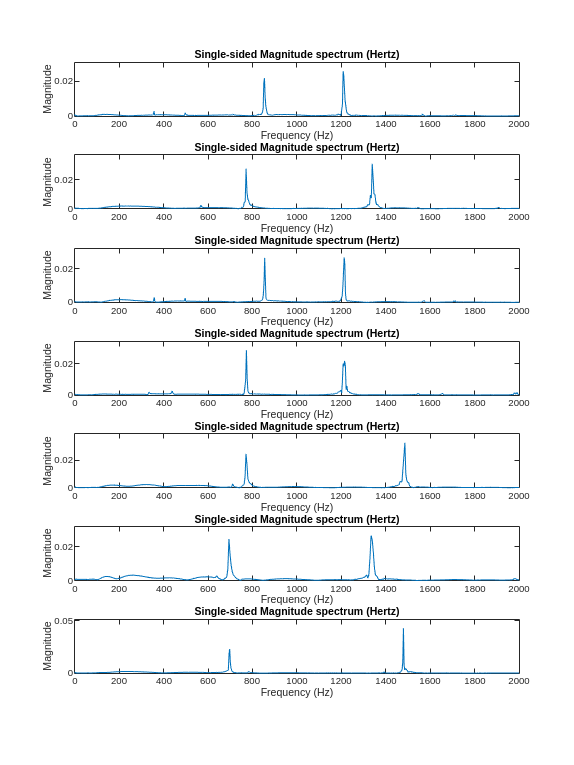

  854.0956  771.3703  855.0119  772.7370  770.9640  694.1758  697.6135

   1.0e+03 *

    1.2080    1.3389    1.2127    1.2148    1.4859    1.3338    1.4794

Phone Number: 7574623


decodeNum('phone_number_audio_recordings/phone_number_6.mp3')

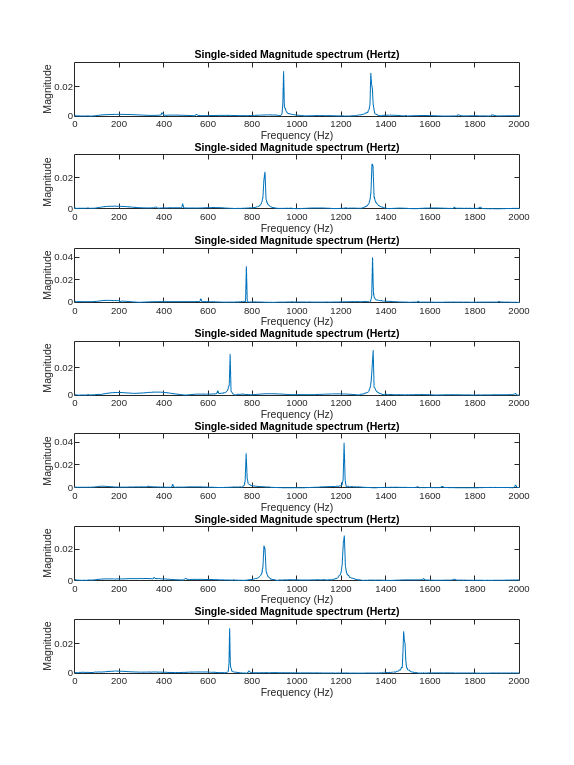

  940.1779  856.4455  772.7159  699.6193  771.5893  851.8291  697.3836

   1.0e+03 *

    1.3325    1.3379    1.3404    1.3433    1.2125    1.2135    1.4804

Phone Number: 0852473


decodeNum('phone_number_audio_recordings/phone_number_7.mp3')

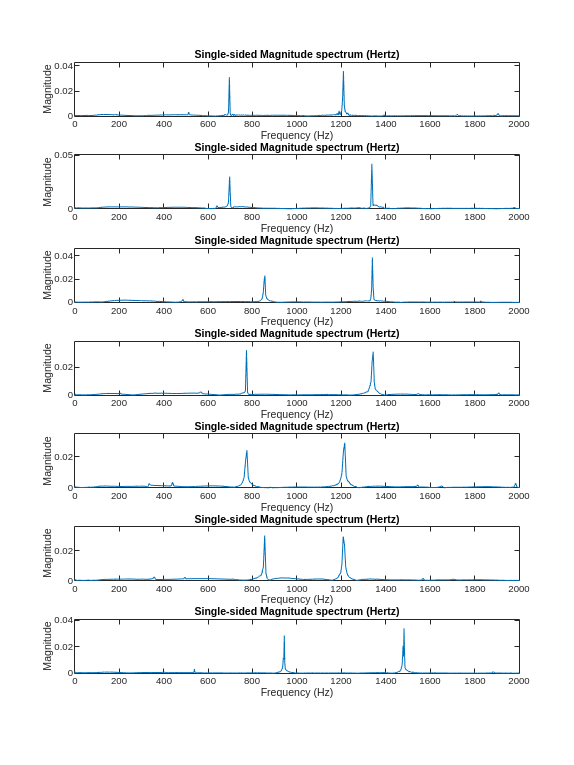

  696.1111  697.2743  855.9729  773.1755  775.0984  854.9826  943.3394

   1.0e+03 *

    1.2094    1.3373    1.3396    1.3434    1.2154    1.2084    1.4821

Phone Number: 128547#


decodeNum('phone_number_audio_recordings/phone_number_8.mp3')

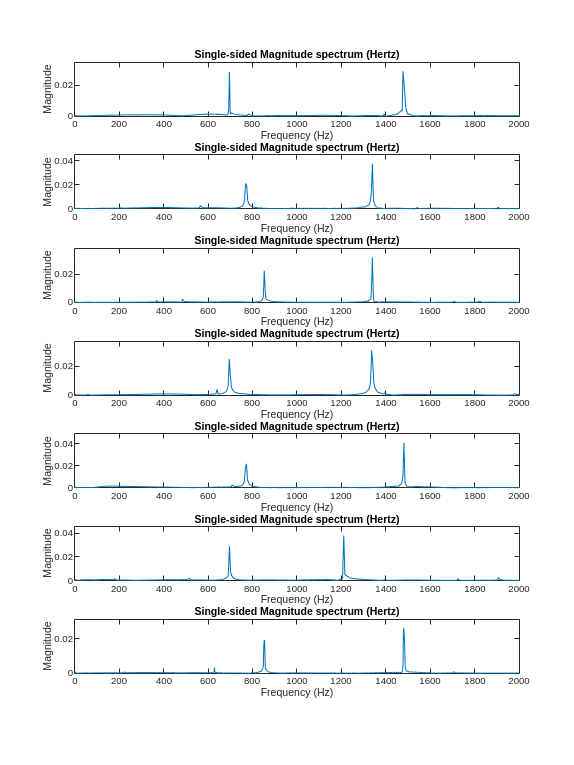

  696.3740  769.0173  853.0026  695.5052  773.0384  696.4286  852.7571

   1.0e+03 *

    1.4775    1.3397    1.3394    1.3364    1.4817    1.2107    1.4797

Phone Number: 3582619


decodeNum('phone_number_audio_recordings/phone_number_9.mp3')